# MAE 342 Final Project ADCS/GNC Graphics

Richard Zhu

emdist = 384400e3; % earth-moon avg dist in m, NASA
[X, Y] = meshgrid(0:emdist/30:emdist, 0:emdist/30:emdist);
mue = 6.67e-11 * 5.972e24; % gravitational constant of Earth
mum = 6.67e-11 * 7.348e22; % gravitational constant of moon
mus = 6.67e-11 * 1.989e30; % gravitational constant of Sun
ms = 1121; % mass of satellite (kg)
re = 6378e3; % radius of Earth (m)



**SRP**

s = 0:0.01:2; % reflectivity, 0 is transparent, 1 is fully absorptive, 2 is reflective
A_m = (0.00195:0.0001:0.005)'; % A/m, m^2/kg
P_s = 4.7e-6; % solar flux / speed of light (N/m2)
a_r = 1; % ratio of sun-earth dist to sun-satellite dist

1.5*0.00195*P_s*a_r*ms * 0.00398980 % N

ans = 6.1487e-08

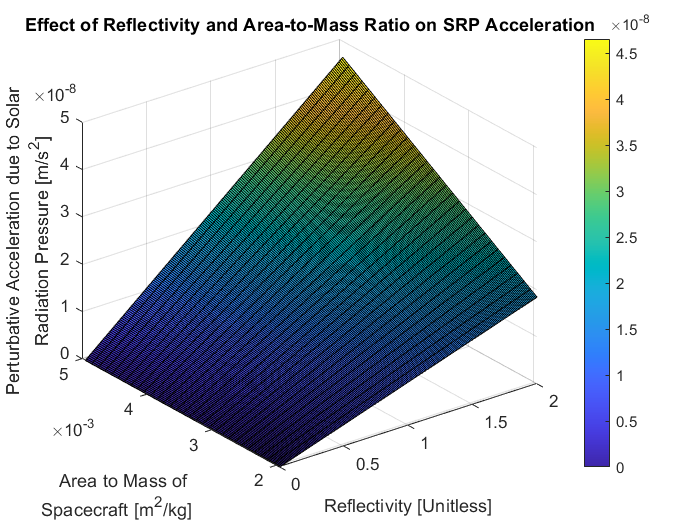


[S, A_M] = meshgrid(s, A_m);
f_srp1 = s.*A_m*P_s*a_r;
F_srp1 = griddata(S,A_M,f_srp1,S,A_M);
surf(S,A_M,F_srp1)
colorbar
title("Effect of Reflectivity and Area-to-Mass Ratio on SRP Acceleration")
xlabel("Reflectivity [Unitless]")
ylabel({"Area to Mass of "; "Spacecraft [m^2/kg]"})
zlabel({"Perturbative Acceleration due to Solar";"Radiation Pressure [m/s^2]"})

**Gravity Gradient**

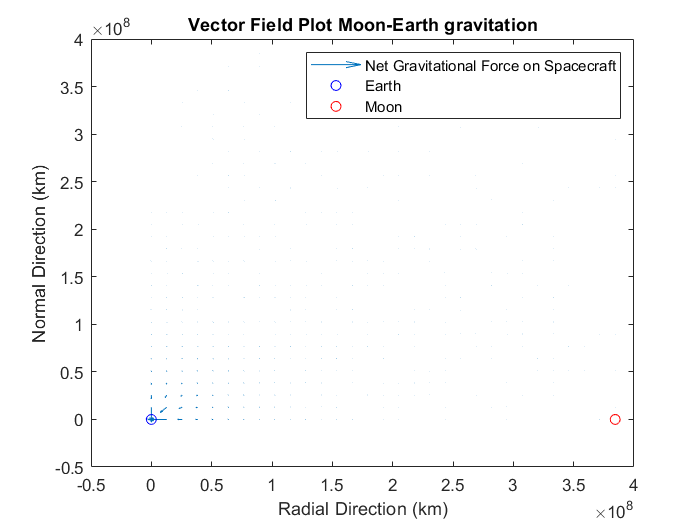

% gravitational force from Earth
R = (X.^2 + Y.^2).^0.5; % radial distance from Earth to each point
R(1,1) = Inf; % gravitational force undefined at center of earth
fx =  -mue * ms * X ./ R.^3; % total force in radial dir
fy = -mue * ms * Y ./ R.^3; % total force in normal dir


% gravitational force from Moon
R = ((X-emdist).^2 + Y.^2).^0.5; % radial distance from Moon to each point
fx = fx + mum*ms*(emdist-X)./R.^3;
fy = fy - mum*ms*Y./R.^3;


% taking log of data

fx(isinf(fx)) = 0;
fy(isinf(fy)) = 0;
quiver(X, Y, fx, fy);
hold on
title("Vector Field Plot Moon-Earth gravitation")
xlabel("Radial Direction (km)")
ylabel("Normal Direction (km)")
plot(0, 0, 'bo')
plot(emdist, 0, 'ro')
legend('Net Gravitational Force on Spacecraft', 'Earth', 'Moon')
% insert images into graph
hold off

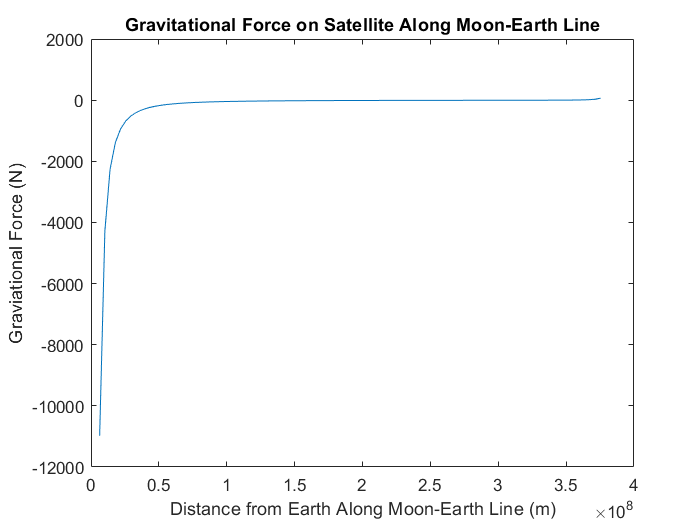

r = re:emdist/100:emdist-re;
plot(r, - mue*ms./r.^2 + mum*ms./(emdist-r).^2)
title("Gravitational Force on Satellite Along Moon-Earth Line")
xlabel("Distance from Earth Along Moon-Earth Line (m)")
ylabel("Graviational Force (N)")

del_fx = gradient(fx)/(R(2)-R(1));
del_fx(isnan(del_fx)) = 0

del_fx =    -0.0127   -0.0016    0.0057    0.0012    0.0005    0.0002    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001         0         0
   -0.0045   -0.0011    0.0016    0.0008    0.0004    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0001
   -0.0011   -0.0006    0.0002    0.0003    0.0002    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
   -0.0004   -0.0003   -0.0000    0.0001    0.0001    0.00

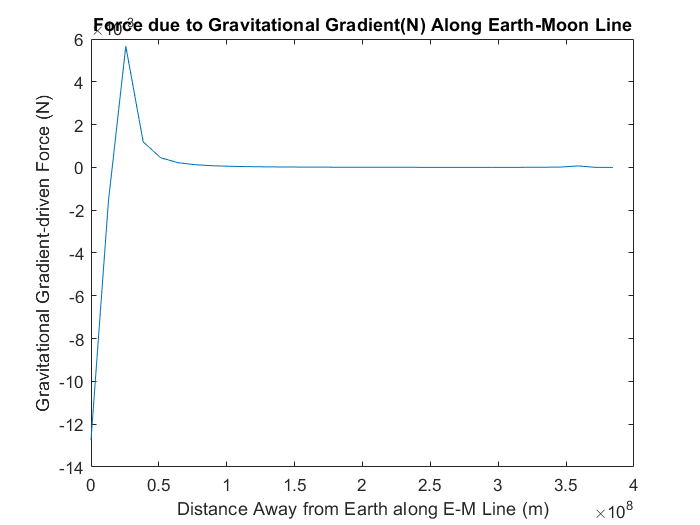

plot(X(1, :), del_fx(1, :))
title("Force due to Gravitational Gradient(N) Along Earth-Moon Line")
xlabel("Distance Away from Earth along E-M Line (m)")
ylabel("Gravitational Gradient-driven Force (N)")

del_fx(1, :)

ans =    -0.0127   -0.0016    0.0057    0.0012    0.0005    0.0002    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001         0         0


del_fx(1, 29)*0.00398980 % N

ans = 2.8258e-07